**LEP 7-3a : Use of regression to find rate law parameters**

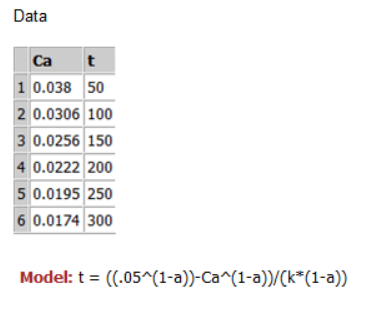

t=[0;50;100;150;200;250;300];%Experimental time(min)value
Ca=[0.05;0.038;0.0306;0.0256;0.0222;0.0195;0.0174];% Experimental Ca(mol/dm^3) value
yo=[3;0.1];%Initial guess vector for a and k
yfinal= nlinfit(Ca,t,@ODEfun,yo);
a=yfinal(1);
k=yfinal(2);
disp('The final value of alpha and k(dm^3/mol.min) are')

The final value of alpha and k(dm^3/mol.min) are


a

a = 2.0447

k

k = 0.1467


t1=[0;50;100;150;200;250;300];%Experimental time(min)value
Ca1=[0.05;0.038;0.0306;0.0256;0.0222;0.0195;0.0174];% Experimental Ca(mol/dm^3) value
yo1=[0.1];%Initial guess vector for k
yfinal1= nlinfit(Ca1,t1,@ODEfun1,yo1);
k=yfinal1(1);
disp('With alpha =2')

With alpha =2


disp('The final value of k(dm^3/mol.min) is')

The final value of k(dm^3/mol.min) is


k

k = 0.1253

function t = ODEfun(yo,Ca)
a=yo(1);
k=yo(2);
t=(.05^(1-a)-Ca.^(1-a))/(k*(1-a));% Model
end
function t1 = ODEfun1(yo1,Ca1)
k1=yo1(1);
a1=2;% 2nd order reaction
t1=(.05^(1-a1)-Ca1.^(1-a1))/(k1*(1-a1));% Model
end
